# **Tutorial: Overview of how to use the MINT toolbox -  PID**

This tutorial provides an introduction to using the PID function from the MINT toolbox for Partial Information Decomposition (PID). It begins with a simulation to generate spiking activity data from two neurons responding to four stimuli. The tutorial demonstrates how to use the PID function to compute various information components—synergistic, redundant, and unique—between the neurons. Additionally, it introduces the options for customizing the PID calculation, including redundancy measures, binning methods, and bias corrections.

## Data simulation

We simulate spiking activity of two neurons to four stimuli values as a sum of two poisson processes (one independent and one shared) for each neuron with the following parameter:

Effects on PID Atoms (Redundancy, Synergy, Unique Information):

 1. **Baseline Parameter B:**

    - baseline parameter B (the overall baseline level of activity common to all stimuli)

    -> higher values of B decrease information of individual neurons and thus the joint information because they increased the standard deviation of responses at fixed stimulus and thus made the rate separation α between most and least effective stimuli smaller in standard deviation units

 2. **Parameter beta:**

    -  regulates the dissimilarity of tuning of the spike count of each individual neuron to the two stimulus features (β close to zero means independent tuning, higher values of β close to β = 0.5 indicate that both neurons encode the features similarly and redundantly)

    -> increase beta to increase the amount of redundancy

 3. **Shared Process Parameter gamma**

    - regulates the strength of the shared process

    -> increasing gamma increases the redundancy

 4. **Stimulus-Tuning Parameter alpha:**

    - regulating the strength of stimulus tuning of the spike counts of the individual neurons 

    -> higher values of alpha leading to higher values of individual neuron information and thus to higher values of joint information 

B = 5;             
beta = 0.3;       
gamma = 20;    
alpha = 10;           

% Based on the above specified parameter we now define the spike rates of the two neurons
rateX1 = B + alpha*beta*[1,1,0,0] + alpha*(1-beta)*[1,0,1,0];
rateX2 = B + alpha*beta*[1,0,1,0] + alpha*(1-beta)*[1,1,0,0];
rateShared = gamma*[1,1,1,1];

nStimuli = length(rateX1);
nTrials_perStimuli = 100;
nTrials = nTrials_perStimuli*nStimuli;
nTimepoints = 30;
stimuli_w = 10:20;

X1 = zeros(1, nTimepoints, nTrials);
X2 = zeros(1, nTimepoints, nTrials);

% Now we simulate the spike trains for X1 and X2 as a sum of the individual spikes and the shared process
for timepoint = 1:nTimepoints
    if ismember(timepoint, stimuli_w)
        X1(1, timepoint, :) = [poissrnd(rateX1(1),1,nTrials/4) poissrnd(rateX1(2),1,nTrials/4)  poissrnd(rateX1(3),1,nTrials/4) poissrnd(rateX1(4),1,nTrials/4)];
        X2(1, timepoint, :) = [poissrnd(rateX2(1),1,nTrials/4) poissrnd(rateX2(2),1,nTrials/4)  poissrnd(rateX2(3),1,nTrials/4) poissrnd(rateX2(4),1,nTrials/4)];
    else
        X1(1, timepoint, :) = poissrnd(B,1, nTrials);
        X2(1, timepoint, :) = poissrnd(B,1, nTrials);
    end
    Xshared(1, timepoint, :) = [poissrnd(rateShared(1),1,nTrials/4) poissrnd(rateShared(2),1,nTrials/4)  poissrnd(rateShared(3),1,nTrials/4) poissrnd(rateShared(4),1,nTrials/4)];
end
X1 = X1 + Xshared;
X2 = X2 + Xshared;
% Now we simulate the stimulus:
S = [ones(1,nTrials/4) 2*ones(1,nTrials/4) 3*ones(1,nTrials/4) 4*ones(1,nTrials/4)];

% smooth data
% Smooth the data
windowSize = 4;
X1 = movmean(X1, windowSize, 2);
X2 = movmean(X2, windowSize, 2);

### Settings of PID

MINT offers the following PID outputs:

- 'Syn'             : the synergistic component of the source neurons about the target

- 'Red'             : the redundant component of the source neurons about the target

- 'Unq1'           : the unique component of the first source neuron about the target

- 'Unq2'           : the unique component of the second source neuron about the target

- 'Unq'             : the sum of the unique components of the source neurons about the target

- 'PID_atoms'  : All the PID atoms (for two sources: Syn, Red, Unq1, Unq2 (in that order))

- 'Joint'            : The sum of all the PID atoms, equal to the joint information of the sources about the targ

- 'Union'          : The sum of the atoms 'Red', 'Unq' 

- 'q_dist'          : This output option is available only when the redundancy measure is set to 'I_BROJA'.    

- 'all'                : outputs all ouputs described above in the following order: {'Syn', 'Red', 'Unq1', 'Unq2', 'Unq', 'Joint', 'Union', ('q_dist')} 

The 'q_dist' is the probability distribution derived from the Broja optimization process. This optimization seeks to maximize the joint information while maintaining the  pairwise marginals at specified target values.

To compute PID you can specify the inputs and requested outputs as follows:

inputs = {X1, X2, S};
reqOutputs = {'Joint','PID_atoms'};

The MINT toolbox allows you to define optional parameters using a structure with various fields. For PID computation, you can specify the following options. If not provided, the function will use default options automatically.

The options you can define are: 

- 'redundancy_measure' : specifies the way the information quantity of each atom                             (default: I_BROJA)

- 'bin_method'                 : specifies the method used to bin the data                                                   (default: none)                     

- 'n_bins'                         : specifies the number of bins                                                                        (default: 3)   CHANGE TO 2

- 'bias'                             : specifies the bias correction method                                                            (default: naive)

- ('xtrp'/'shuff')                 : further specification for the bias correction methods 'qe' and 'shuffSub'      (default: 10 xtrp/20 shuff)

- 'pid_constrained'          : constrained PID or unconstrained                                                                (default: true)

- 'supressWarnings'        : option to supress warnings e.g. for missing opts fields                                (default: false)

- 'NaN_handling'             : specify how to deal with NaN values in the data                                          (default: error)

To get more information for the binning procedure or the bias correction type `help binning` or `help correction` in your Command Window

PID_opts.redundancy_measure = 'I_min';      % Options:                                                  
                                            % 'I_BROJA'
                                            % 'I_MMI'
                                            % 'I_min'                                              

% To bin your data, you must specify both the binning method and the number of bins. You can set different methods 
% or number of bins for each input. If only one is provided, it will be applied to all inputs. 
% For more details type 'help binning' in your Command Window.
PID_opts.bin_method = {'eqpop', 'eqpop', 'none'};   % Options:                                         
                                                    % 'eqpop' (equal population), 
                                                    % 'eqspace' (equal spacing)
                                                    % 'threshold'
                                                    % 'none' (no binning)                                   
PID_opts.n_bins = {3, 3};                           % Specify an integer for the number of bins         


% To correct for sampling bias, you can specify methods for bias correction in the MINT toolbox. If its not naive 
% you will get the naive values as the second output of the functions. 
% For more details type 'help correction' in your Command Window. 
PID_opts.bias = 'qe_shuffSub';                            % Options:                                        
                                                    % 'naive' (no bias correction)                                                                   
                                                    % 'qe' (Quadratic Extrapolation), 
                                                    % 'le' (Linear Extrapolation), 
                                                    % 'qe_shuffSub' (Quadratic with Shuffle Subtraction), 
                                                    % 'le_shuffSub' (Linear with Shuffle Subtraction), 
                                                    % 'shuffSub' (Shuffle Subtraction), 

% If you use 'qe' you have to specify the number of extrapolations (opts.xtrp) the correction function should to. 
% If you use 'shuffSub' you have to specify the number of shufflings (opts.shuff) the correction function should to. 
PID_opts.xtrp = 6;   
PID_opts.shuff = 2; 
% In the case of two sources and one target MINT offers the option for shuffSub and qe, to compute the corrected PID atoms constrained to 
% the corrected information. This can be set with the option opts.pid_constrained:
PID_opts.pid_constrained = true;                    % Options.                                          
                                                    % true/false

% Several functions give you warning, e.g. if you did not specify an opts field that is needed and the function is 
% using the default it will inform you. If you don't want to get these warning you can supress them with the opts field 
% supressWarnings (default: false).
PID_opts.supressWarnings = false;

PID_opts.NaN_handling = 'removeTrial';              % Options:                                          
                                                    % 'error' (Throws an error if NaN values are detected in any input)
                                                    % 'removeTrial' (Removes trials (across all variables) that contain NaN values)  

### Generating null distributions

To test for significance, you may want to generate a null distribution.The functions in the MINT toolbox offer an option to do this through the `opts.computeNulldist` parameter. To obtain the null distribution, set this option to `true` and specify the number of samples using `opts.n_samples` (default is 100). 

You can also indicate which variables should be shuffled to create the null distribution or specify if the shuffling should be conditioned on another variable using `opts.shuffling`. If you provide multiple shuffling definitions, the function will output one null distribution for each shuffling definition specified. (default: 'A' (just the firstinput variable is going to be shuffled). 

You can also specify the dimension that should be shuffled with opts.dim_shuffle. For 'Trials' it shuffles the last dimension, for 'Objects' the first and for 'Timepoints' the second.

For more information, type `help create_nullDist` in your Command Window.

PID_opts.computeNulldist = false;   % set to true to compute the null Distribution. If you want to make the script faster set to false  
PID_opts.parallel_sampling = true;   
PID_opts.n_samples = 20;
PID_opts.shuffling = {'AB', 'A'};
PID_opts.dim_shuffle = {'Trials'};

### PID Outputs

The function can output three variables based on the specified settings:

- **PID_values**: This is a cell array containing the PID values based on the specified reqOutputs argument. Each cell represents one requested output in the same order as specified

- **PID_naive**: This cell array contains the naive estimates. These estimates are calculated without any bias correction. It is important to note that if no bias correction is performed during the computation, the PID_values will be identical to the PID_naive values.

- **PID_nullDist**: This output contains the results of the null distribution computation, which is useful for significance testing. If the null distribution is not computed, this output will be zero.

### Compute PID

Now we definied all possible options and we can compute the PID values with the following function call. As the inputs X1 and X2 are the spike trains over time, the output will give the PID atoms over time:

[PID_corrected, PID_naive, PID_nullDist] =   PID(inputs, reqOutputs, PID_opts); 

### Plot Results

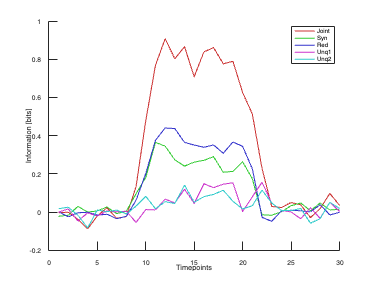

% PID_corrected{1} = Joint
% PID_corrected{2} = Synergy
% PID_corrected{3} = Redundancy
% PID_corrected{4} = Unique1
% PID_corrected{5} = Unique2

x = 1:nTimepoints;
figure;
hold on;
colors = [
    0.8, 0.2, 0.2;  
    0.2, 0.8, 0.2;  
    0.2, 0.2, 0.8;  
    0.8, 0.2, 0.8;  
    0.2, 0.8, 0.8   
];
plot(x, PID_corrected{1}, 'Color', colors(1,:), 'LineWidth', 1.5, 'DisplayName', 'Joint');
plot(x, PID_corrected{2}, 'Color', colors(2,:), 'LineWidth', 1.5, 'DisplayName', 'Syn');
plot(x, PID_corrected{3}, 'Color', colors(3,:), 'LineWidth', 1.5, 'DisplayName', 'Red');
plot(x, PID_corrected{4}, 'Color', colors(4,:), 'LineWidth', 1.5, 'DisplayName', 'Unq1');
plot(x, PID_corrected{5}, 'Color', colors(5,:), 'LineWidth', 1.5, 'DisplayName', 'Unq2');

% Customize plot
xlabel('Timepoints');
ylabel('Information [bits]');
legend('show');
hold off;